[signal, Fs] = audioread("audio_piano.m4a");

sound(signal, Fs);

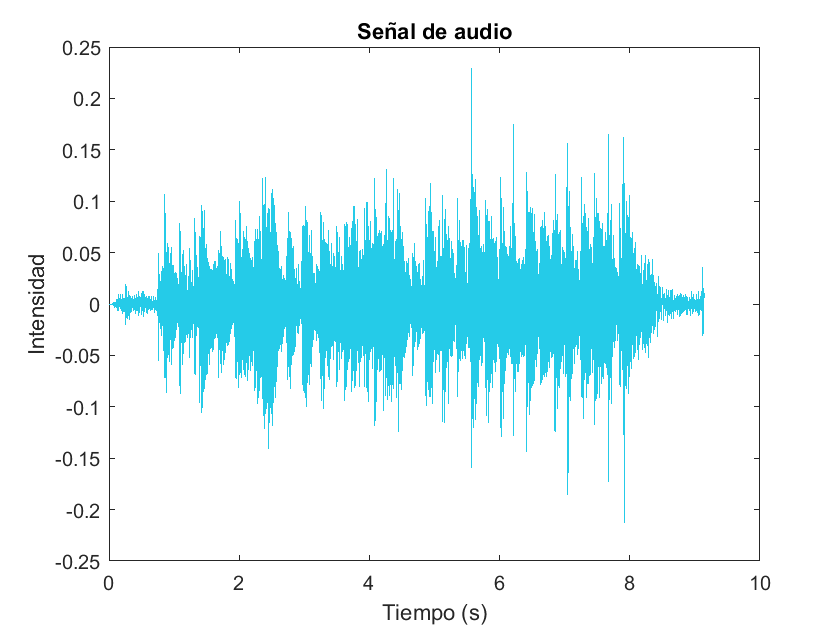

deltaT = 1/Fs;
tArray = (0:length(signal)-1)*deltaT;

figure()
plot(tArray, signal, "Color", "#25cbe8");
title("Señal de audio")
xlabel("Tiempo (s)")
ylabel("Intensidad")

hilbertTransformer = HilbertHuangTransform();

[modes, residue] = hilbertTransformer.getIntrinsicModeFunctions(signal', 5, 10);

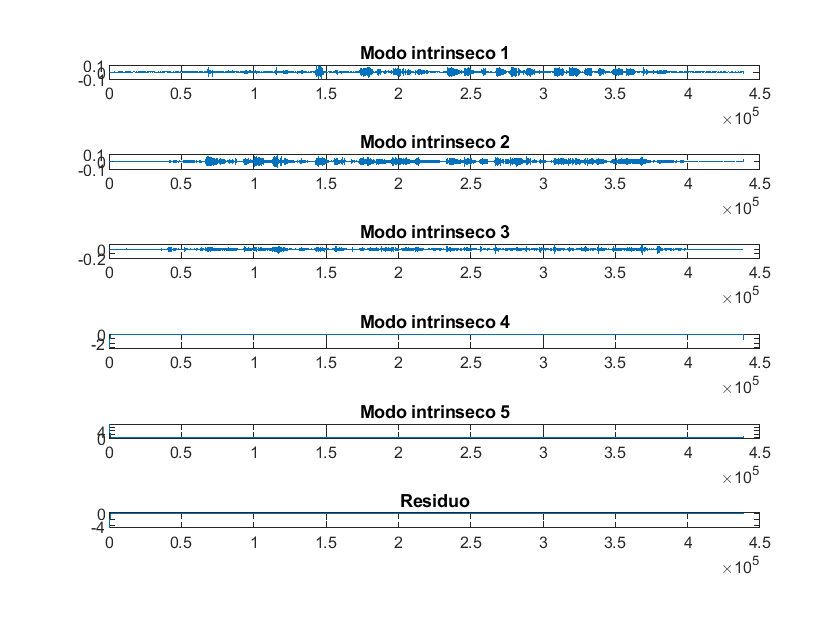


figure()
hold on 
for i = 1:length(modes)
    intrinsicMode = modes{i};
    subplot(length(modes) + 1,1,i);
    plot(intrinsicMode)
    title("Modo intrinseco "+string(i))
end

subplot(length(modes) +1,1,length(modes) + 1)
plot(residue)
title("Residuo")

sound(modes{2}, Fs);
